clc
clear

ke=10;
elasticdt=0.005;
plasticdt=0.005/100;
%initial value
Q=[0;0;0;0;0;0];
Qy=4000;
jj=1;
for i=0:elasticdt:20
    q(1,jj)=1*i^2;
    q(2,jj)=2*i^2;
    q(3,jj)=3*i^2;
    q(4,jj)=4*i^2;
    q(5,jj)=5*i^2;
    q(6,jj)=6*i^2;
    jj=jj+1;
end
t=0:elasticdt:20;
dotq(:,1)=zeros(6,1);
for i=2:size(q,2)
    dotq(:,i)=(q(:,i)-q(:,i-1))/elasticdt;
end

if norm(Q(:,1))-Qy>0
else
    iflag=0;
end

for i=1:271787
    if iflag==0
        Q(:,i+1)=Q(:,i)+ke*dotq(:,i+1)*elasticdt;
        if norm(Q(:,i+1))-Qy>0
            if Q(:,i+1)'*dotq(:,i+1)<0
                iflag=0;
                Q(:,i+1)=Q(:,i)+ke*dotq(:,i+1)*elasticdt;
            else
                iflag=1;
                kj=i+2;
                syms dt
                f=Q(:,i)+ke*dotq(:,i+1)*dt;
                f1=norm(f)-Qy;
                dt1=solve(f1,dt);
                dt=double(dt1);
                aa=find (dt<0);
                dt(aa)=[];
                Q(:,i+1)=Q(:,i)+ke*dotq(:,i+1)*dt;%Qton
                elat=(i-1)*elasticdt+dt;
                t(:,i+1)=elat
                q(:,i+1)=Q(:,i+1)/ke;
                jj=i+2
                for ill=elat+plasticdt:plasticdt:20
                    q(1,jj)=1*ill^2;
                    q(2,jj)=2*ill^2;
                    q(3,jj)=3*ill^2;
                    q(4,jj)=4*ill^2;
                    q(5,jj)=5*ill^2;
                    q(6,jj)=6*ill^2;
                    jj=jj+1;
                end
                for i1=i+2:size(q,2)
                    dotq(:,i1)=(q(:,i1)-q(:,i1-1))/plasticdt;
                end
                ik=1;
                
            end
        end
    end
    if iflag==1 && ik==0
        Q(:,i+1)=Q(:,i)+(-ke*Q(:,i)'*dotq(:,i+1)*Q(:,i)/(Qy*Qy)+dotq(:,i+1)*ke)*plasticdt;
        if Q(:,i+1)'*dotq(:,i+1)<0
            iflag=0;
            Q(:,i+1)=Q(:,i)+ke*dotq(:,i+1)*elasticdt;
        end
    end
    ik=0;
end

t =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


jj = 1298

t(:,kj:end)=[];
t=[t,elat+plasticdt:plasticdt:20];

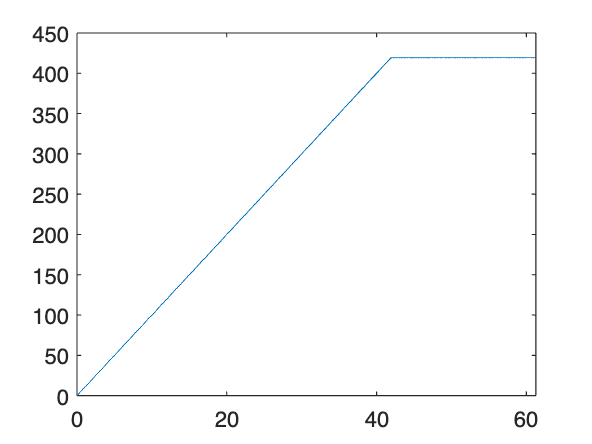

% plot(Q(1,1:50000),Q(2,1:50000))
plot(q(1,1:28335),Q(1,1:28335))

kk=[];
for i=1:size(Q,2)
    kk(:,i)=norm(Q(:,i))-Qy;
end